# Modifying a Local Function

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and plots the distribution of total medal counts

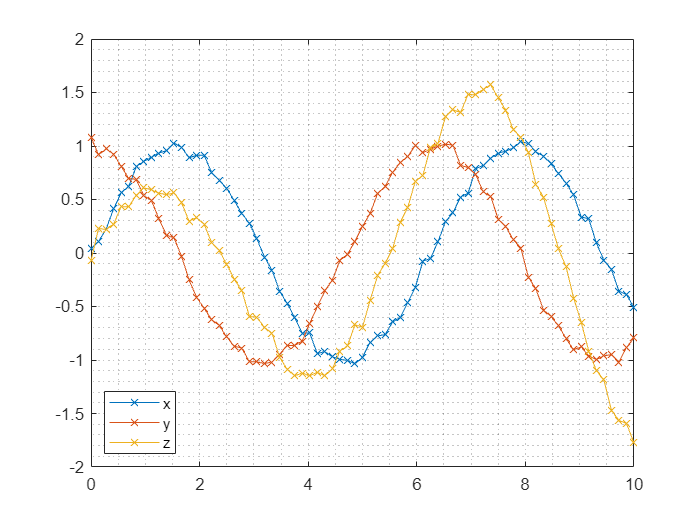

rng(123)
n = 73;
t = linspace(0, 10, n);
x = sin(t) + 0.05*randn(1, n);
y = cos(t) + 0.05*randn(1, n);
z = 0.4*sqrt(t).*(sin(t)+cos(t)) + 0.05*randn(1, n);

plot(t, x, "x-", t, y, "x-", t, z, "x-")
grid minor
legend(["x", "y", "z"], "Location", "southwest")

## Task 1

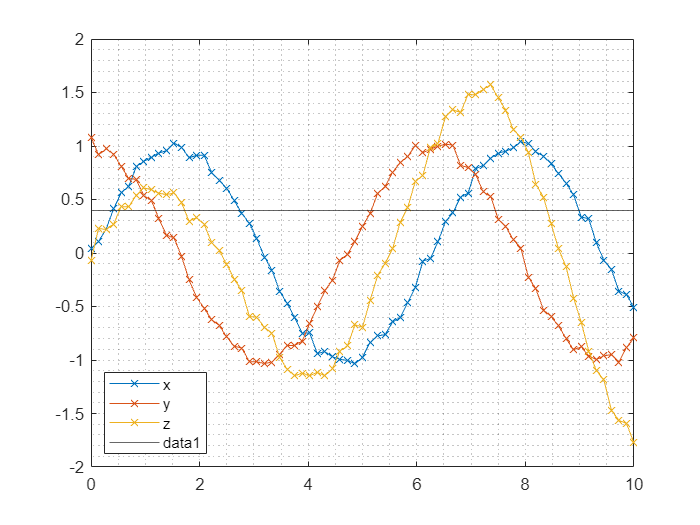

y0 = 0.4;
yline(y0)


tzerox = findcrossing(t,x,y0)

tzerox =     0.4060    2.7436    6.6888    8.9848


tzeroy = findcrossing(t,y,y0)

tzeroy =     1.1860    5.1627    7.4448


## Task 2

tcross = findcrossing(t,x,y)

tcross =     0.7472    3.9527    7.0589


function xcross = findcrossing(x,y,z)
y = y - z;
% Indices where current value and next value have opposite sign
idx = find(y(1:end-1).*y(2:end) <= 0);
% Linear interpolation between indices and next point
xcross = (x(idx).*y(idx+1) - x(idx+1).*y(idx))./(y(idx+1)-y(idx));
end